%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% EXERCISE 2

syms x y r

fx = -r*x + y

$$fx = y-r\,x$$

fy = (x^2/(1+x^2))-y

$$fy = \frac{x^{2}}{x^{2}+1}-y$$


% CALCULATE THE FIXED POINTS
disp('Fixed Points as a function of r:')

Fixed Points as a function of r:


[fp_x, fp_y] = solve([fx; fy], [x; y]);
fixPts = [fp_x, fp_y]'

$$fixPts = \begin{array}{l} \left(\begin{array}{ccc} \frac{\sigma_{1}+\frac{1}{2}}{\bar{r}} & -\frac{\sigma_{1}-\frac{1}{2}}{\bar{r}} & 0\\ \sigma_{1}+\frac{1}{2} & \frac{1}{2}-\sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\bar{\sqrt{-\left(2\,r-1\right)\,\left(2\,r+1\right)}}}{2} \end{array}$$


disp('As it can be seen in the Fixed Points, we have three bifurcation points at r=-1/2, r=0 and r=1/2. Thus, we will have seven regions, shown below:')

As it can be seen in the Fixed Points, we have three bifurcation points at r=-1/2, r=0 and r=1/2. Thus, we will have seven regions, shown below:


ZONE 1: For r<-1/2

disp('ZONE 1: r<-1/2')

ZONE 1: r<-1/2



% we choose a value r<-1/2 -> r=-1
fx1 = subs(fx, r, -1);
fy1 = subs(fy, r, -1);

% setting the matlab function for our system
f_lmb1 = @(t,z) [z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0, keeping one as two are imaginary
fixPts1 = subs(fixPts, r, -1);
fixPts1 = fixPts1(:, 3)

$$fixPts1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

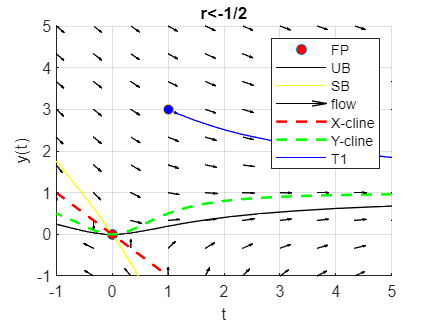


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts1, 2));
eigenvalues = zeros(size(fixPts1, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts1, 2));

for k = 1:size(fixPts1, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx1, fy1], [x, y]), {x, y}, {fixPts1(1, k), fixPts1(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts1(1,:), fixPts1(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx1 == 0, x);
ycline_y = solve(fy1 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx1, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy1, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx1, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy1, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 10;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts1(:,1));
[ts,ys] = ode45(f_lmb1,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[1 3];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb1,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('r<-1/2')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('We have a saddle (unstable). We know that the only real part is the positive quadrant. However, we represent some negative values in order to show the characteristics of the Fixed Points.')

We have a saddle (unstable). We know that the only real part is the positive quadrant. However, we represent some negative values in order to show the characteristics of the Fixed Points.


ZONE 2: For r=-1/2

disp('ZONE 2: r=-1/2')

ZONE 2: r=-1/2



% we choose a value r=-1/2
fx2 = subs(fx, r, -1/2);
fy2 = subs(fy, r, -1/2);

% setting the matlab function for our system
f_lmb2 = @(t,z) [(1/2)*z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0 and in this case keep two as they are the same
fixPts2 = subs(fixPts, r, -1/2);
fixPts2 = fixPts2(:, 2:3)

$$fixPts2 = \left(\begin{array}{cc} -1 & 0\\ \frac{1}{2} & 0 \end{array}\right)$$

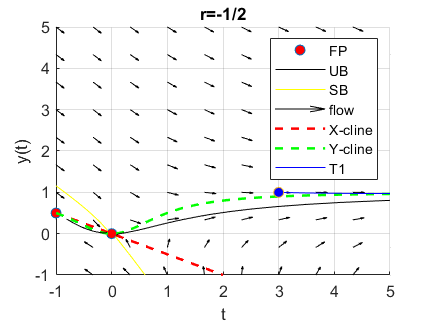


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts2, 2));
eigenvalues = zeros(size(fixPts2, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts2, 2));

for k = 1:size(fixPts2, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx2, fy2], [x, y]), {x, y}, {fixPts2(1, k), fixPts2(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts2(1,:), fixPts2(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx2 == 0, x);
ycline_y = solve(fy2 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx2, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy2, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx2, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy2, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 10;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts2(:,2));
[ts,ys] = ode45(f_lmb2,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts2(:,2));
[ts,ys] = ode45(f_lmb2,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts2(:,2));
[ts,ys] = ode45(f_lmb2,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts2(:,2));
[ts,ys] = ode45(f_lmb2,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 = [3 1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb2,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('r=-1/2')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('We have a non-isolated fixed point (stable) and a saddle (unstable).')

We have a non-isolated fixed point (stable) and a saddle (unstable).


ZONE 3: For -1/2<r<0

disp('ZONE 3: -1/2<r<0')

ZONE 3: -1/2<r<0



% we choose a value -1/2<r<0 -> r=-1/4
fx3 = subs(fx, r, -1/4);
fy3 = subs(fy, r, -1/4);

% setting the matlab function for our system
f_lmb3 = @(t,z) [1/4*z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0
fixPts3 = double(subs(fixPts, r, -1/4))

fixPts3 =    -3.7321   -0.2679         0
    0.9330    0.0670         0


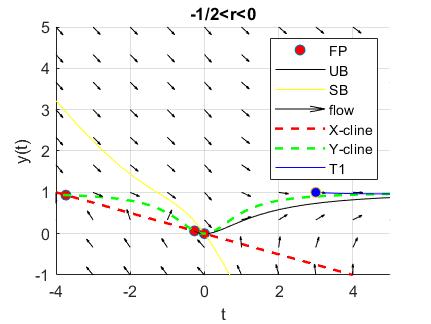


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts3, 2));
eigenvalues = zeros(size(fixPts3, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts3, 2));

for k = 1:size(fixPts3, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx3, fy3], [x, y]), {x, y}, {fixPts3(1, k), fixPts3(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

h1 = figure;
hold on;
grid on;
fpts = plot(fixPts3(1,:), fixPts3(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx3 == 0, x);
ycline_y = solve(fy3 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx3, [-4 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy3, [-4 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-4, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx3, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy3, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 50;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts3(:,3));
[ts,ys] = ode45(f_lmb3,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts3(:,3));
[ts,ys] = ode45(f_lmb3,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts3(:,3));
[ts,ys] = ode45(f_lmb3,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts3(:,3));
[ts,ys] = ode45(f_lmb3,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 = [3 1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb3,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-4 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('-1/2<r<0')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('Now we have three Fixed Points, two saddles (unstable) and a stable spiral in the middle.')

Now we have three Fixed Points, two saddles (unstable) and a stable spiral in the middle.


ZONE 4: r=0

disp('ZONE 4: r=0')

ZONE 4: r=0



% we choose a value -1/2<r<0 -> r=-1/4
fx4 = subs(fx, r, -1/4);
fy4 = subs(fy, r, -1/4);

% setting the matlab function for our system
f_lmb4 = @(t,z) [z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0
fixPts4 = fixPts(:,3)

$$fixPts4 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

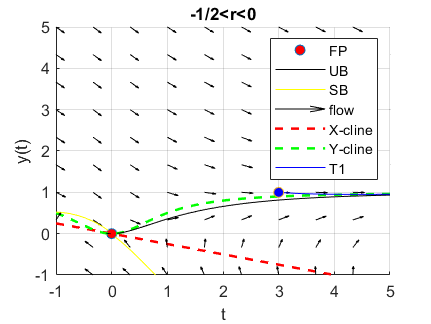


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts4, 2));
eigenvalues = zeros(size(fixPts4, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts4, 2));

for k = 1:size(fixPts4, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx4, fy4], [x, y]), {x, y}, {fixPts4(1, k), fixPts4(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

h1 = figure;
hold on;
grid on;
fpts = plot(fixPts4(1,:), fixPts4(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx4 == 0, x);
ycline_y = solve(fy4 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx4, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy4, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx4, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy4, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 50;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts4(:,1));
[ts,ys] = ode45(f_lmb4,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts4(:,1));
[ts,ys] = ode45(f_lmb4,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts4(:,1));
[ts,ys] = ode45(f_lmb4,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts4(:,1));
[ts,ys] = ode45(f_lmb4,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 = [3 1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb4,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('-1/2<r<0')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('We have a saddle (unstable). We know that the only real part is the positive quadrant. However, we represent some negative values in order to show the characteristics of the Fixed Points.')

We have a saddle (unstable). We know that the only real part is the positive quadrant. However, we represent some negative values in order to show the characteristics of the Fixed Points.


ZONE 5: 0<r<1/2

disp('ZONE 5: 0<r<1/2')

ZONE 5: 0<r<1/2



% we choose a value -1/2<r<0 -> r=-1/4
fx5 = subs(fx, r, 1/4);
fy5 = subs(fy, r, 1/4);

% setting the matlab function for our system
f_lmb5 = @(t,z) [- 1/4*z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0
fixPts5 = double(subs(fixPts, r, 1/4))

fixPts5 =     3.7321    0.2679         0
    0.9330    0.0670         0


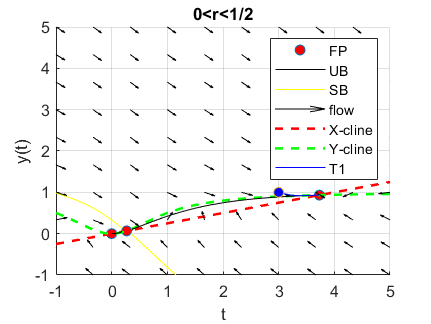


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts5, 2));
eigenvalues = zeros(size(fixPts5, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts5, 2));

for k = 1:size(fixPts5, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx5, fy5], [x, y]), {x, y}, {fixPts5(1, k), fixPts5(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

h1 = figure;
hold on;
grid on;
fpts = plot(fixPts5(1,:), fixPts5(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx5 == 0, x);
ycline_y = solve(fy5 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx5, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy5, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx5, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy5, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 50;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts5(:,2));
[ts,ys] = ode45(f_lmb5,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts5(:,2));
[ts,ys] = ode45(f_lmb5,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts5(:,2));
[ts,ys] = ode45(f_lmb5,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts5(:,2));
[ts,ys] = ode45(f_lmb5,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 = [3 1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb5,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('0<r<1/2')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('Now we have three Fixed Points, two stable nodes and a saddle (unstable) in the middle.')

Now we have three Fixed Points, two stable nodes and a saddle (unstable) in the middle.


ZONE 6: For r=1/2

disp('ZONE 6: r=1/2')

ZONE 6: r=1/2



% we choose a value r=-1/2
fx6 = subs(fx, r, 1/2);
fy6 = subs(fy, r, 1/2);

% setting the matlab function for our system
f_lmb6 = @(t,z) [- (1/2)*z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0 and in this case keep two as they are the same
fixPts6 = subs(fixPts, r, 1/2);
fixPts6 = fixPts6(:, 2:3)

$$fixPts6 = \left(\begin{array}{cc} 1 & 0\\ \frac{1}{2} & 0 \end{array}\right)$$

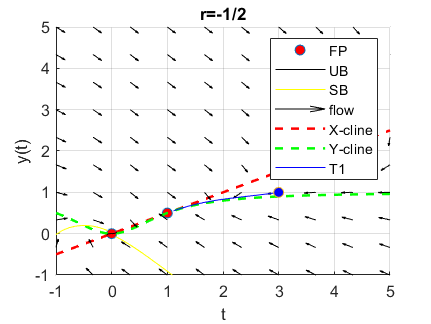


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts6, 2));
eigenvalues = zeros(size(fixPts6, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts6, 2));

for k = 1:size(fixPts6, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx6, fy6], [x, y]), {x, y}, {fixPts6(1, k), fixPts6(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts6(1,:), fixPts6(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx6 == 0, x);
ycline_y = solve(fy6 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx6, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy6, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx6, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy6, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 10;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts6(:,2));
[ts,ys] = ode45(f_lmb6,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts6(:,2));
[ts,ys] = ode45(f_lmb6,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts6(:,2));
[ts,ys] = ode45(f_lmb6,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts6(:,2));
[ts,ys] = ode45(f_lmb6,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 = [3 1];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb6,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('r=-1/2')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('We have a stable non-isolated Fixed Point and a stable node.')

We have a stable non-isolated Fixed Point and a stable node.


ZONE 7: For r>1/2

disp('ZONE 7: r>1/2')

ZONE 7: r>1/2



% we choose a value r>1/2 -> r=1
fx7 = subs(fx, r, 1);
fy7 = subs(fy, r, 1);

% setting the matlab function for our system
f_lmb7 = @(t,z) [- z(1) + z(2);(z(1)^2/(1 + z(1)^2)) - z(2)];

% Computing Fixed points for Zone 1, r=0, keeping one as two are imaginary
fixPts7 = subs(fixPts, r, 1);
fixPts7 = fixPts7(:, 3)

$$fixPts7 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

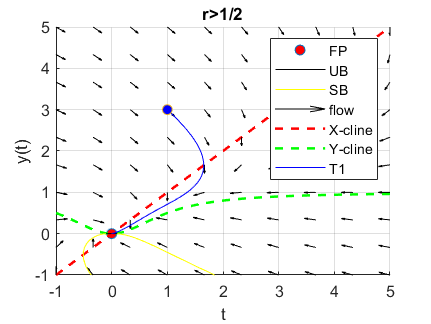


% Computing the jacobian matrix, the eigenvalues and the eigenvectors for the fixed points
JacFixPts = zeros(2, 2, size(fixPts7, 2));
eigenvalues = zeros(size(fixPts7, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts7, 2));

for k = 1:size(fixPts7, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx7, fy7], [x, y]), {x, y}, {fixPts7(1, k), fixPts7(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts7(1,:), fixPts7(2,:), 'o', 'MarkerFaceColor', 'r');

% COMPUTE THE NULLCLINES
xcline_x = solve(fx7 == 0, x);
ycline_y = solve(fy7 == 0, y);

% Representing the nullclines
nullX = fimplicit(fx7, [-1 5 -1 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy7, [-1 5 -1 5], 'g--', 'LineWidth', 1.5);

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(-1, 5, N);
ylin = linspace(-1, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx7, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy7, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing and representing the flow
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% PAINT BASINS
% Setting epsilon
eps = 0.1;
% Setting time
t0 = 0.5; tf = 10;

% Setting Unstable Basin (UB)
tspam = [t0,tf];

y1 = double((eigenvectors(:, 1, 1)*eps)+fixPts7(:,1));
[ts,ys] = ode45(f_lmb7,tspam, y1);
basin1 = plot(ys(:,1),ys(:,2),'black-');

y2 = double(-(eigenvectors(:, 1, 1)*eps)+fixPts7(:,1));
[ts,ys] = ode45(f_lmb7,tspam, y2);
basin2 = plot(ys(:,1),ys(:,2),'black-');

% Setting Stable Basin (SB)
tspam = [tf,t0]; % Reverse time

y3 = double((eigenvectors(:, 2, 1)*eps)+fixPts7(:,1));
[ts,ys] = ode45(f_lmb7,tspam, y3);
basin3 = plot(ys(:,1),ys(:,2),'y-');

y4 = double(-(eigenvectors(:, 2, 1)*eps)+fixPts7(:,1));
[ts,ys] = ode45(f_lmb7,tspam, y4);
basin4 = plot(ys(:,1),ys(:,2),'y-');

% REPRESENT TRAJECTORIES
% Trajectory 1
y0 =[1 3];
t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb7,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% SETTING GRAPH PARAMS
axis([-1 5 -1 5]);
xlabel('t');ylabel('y(t)');grid on; title('r>1/2')
legend([fpts basin1 basin3 flow nullX nullY traj1],{'FP', 'UB', 'SB', 'flow', 'X-cline', 'Y-cline', 'T1'},'Location', 'NorthEast')
hold off


disp('We have a stable node.')

We have a stable node.
